sys = zpk([],[-1 -1 -1],1); 
[C_pi,info] = pidtune(sys,'PI')

C_pi =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 1.14, Ki = 0.454
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 0.5205
           PhaseMargin: 60.0000


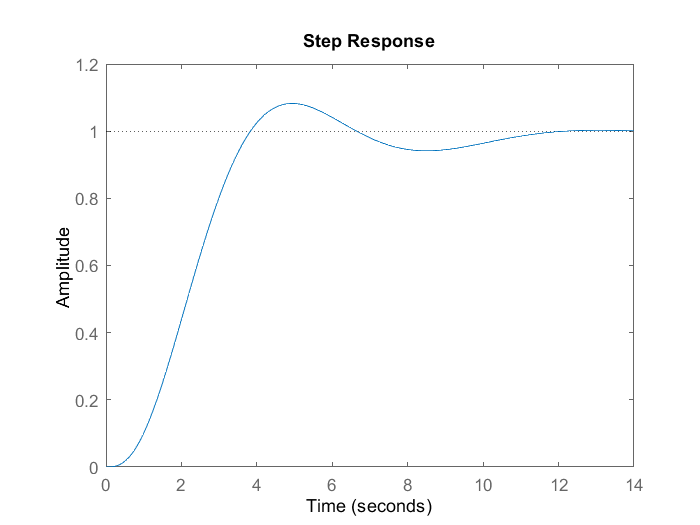

T_pi = feedback(C_pi*sys, 1);
step(T_pi)


[C_pi_fast,info] = pidtune(sys,'PI',1.0)

C_pi_fast =
 
             1 
  Kp + Ki * ---
             s 

  with Kp = 2.83, Ki = 0.0495
 
Continuous-time PI controller in parallel form.



info = struct with fields:
                Stable: 1
    CrossoverFrequency: 1
           PhaseMargin: 43.9973


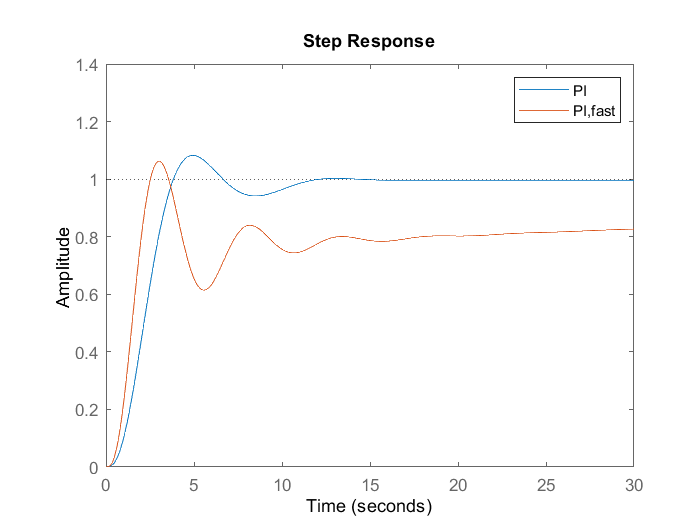

T_pi_fast = feedback(C_pi_fast*sys,1);
step(T_pi,T_pi_fast)

axis([0 30 0 1.4])
legend('PI','PI,fast')

https://www.mathworks.com/help/control/ug/proportional-integral-derivative-pid-controllers.html

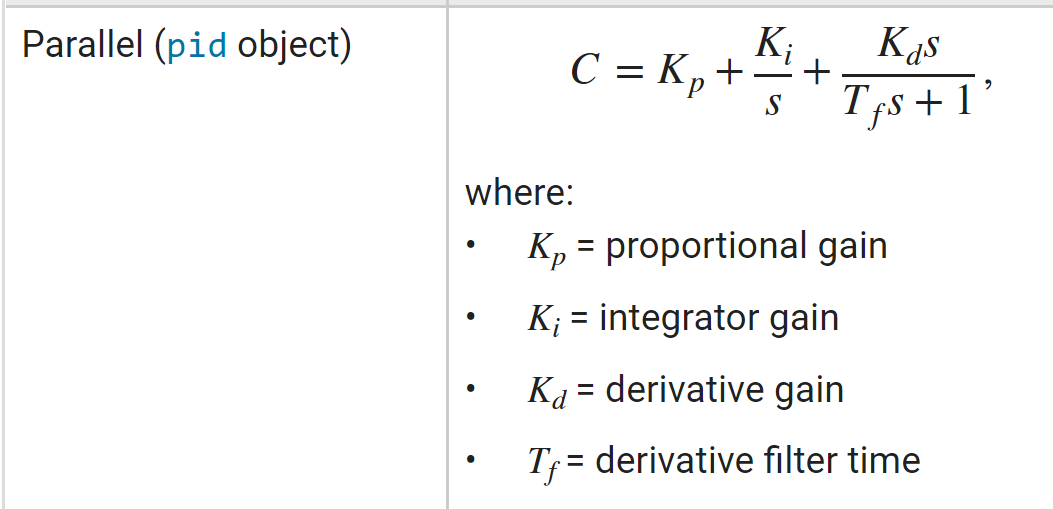

Kp = 29.5;
Ki = 26.2;
Kd = 4.3;
Tf = 0.06; %Time constant of the first-order derivative filter %by default Tf = 0
C = pid(Kp,Ki,Kd,Tf)

C =
 
             1            s    
  Kp + Ki * --- + Kd * --------
             s          Tf*s+1 

  with Kp = 29.5, Ki = 26.2, Kd = 4.3, Tf = 0.06
 
Continuous-time PIDF controller in parallel form.



%C = pid(Kp,Ki,Kd) %by default Tf = 0

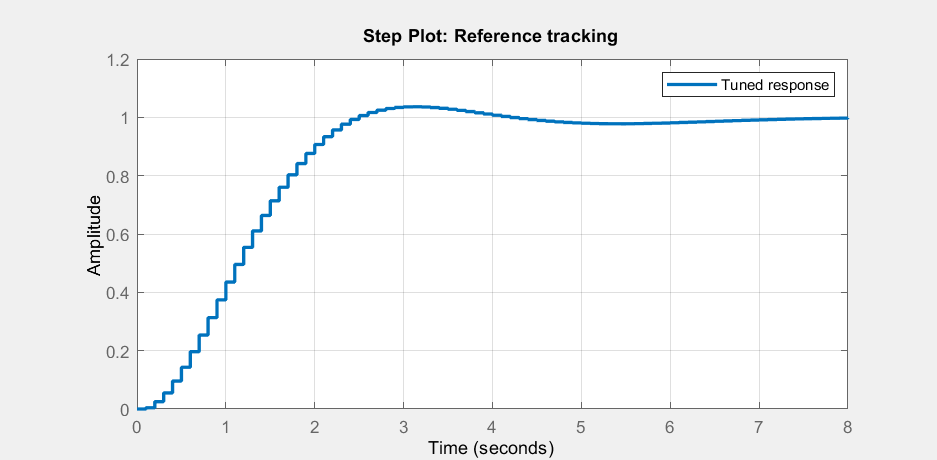

C = pid(1,2,3,'InputName','e','OutputName','u')